# Call-option explorer (Section 5.4 and 6.1)

Volker Ziemann, 211125, CC-BY-SA-4.0

Here we explore how the price $c$ of an European call option depends on the strike price $K$, the time to maturity $T$, the annual volatility $\sigma$, and the risk-free rate $r_f$, which are placed under the control of sliders, such that they can be easily changed.

clear
K=1;  % Slider for the strike price
T=1;  % Slider for the time until maturity [years]
sig=0.3; % Slider for the annual volatility
rf=0.01; % Slider for the annual risk-free rate

After the parameters are known, we select the range of initial stock values $S$ to explore and first calculate the price of the call option as well as the Greeks $\Delta$, $\Gamma$, and $\Theta$ immediately before maturity, which is convenient to dsiplay as reference in some cases. 

S=0:0.01:2.5;
[c0,delta0,gamma0,theta0]=black_scholes_call(S,K,0.00001,rf,sig);

Then we calculate $c$, $\Delta$, $\Gamma$, and $\Theta$ once again for the time $T$ until maturity selected with the slider for the range of the the range of current stock values $S$.

[c,delta,gamma,theta]=black_scholes_call(S,K,T,rf,sig);

Next we plot both the option price immediately before maturity, which is the payoff function, as a black line and the option price $c$ at time $T$ before maturity as a red line, annotate the axis and give the chosen parameters in the legend. 

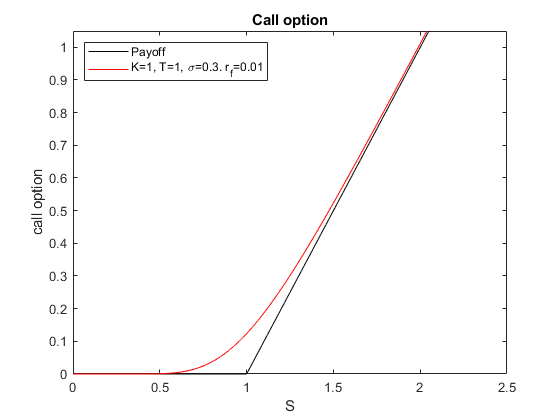

clf; plot(S,c0,'k',S,c,'r')
xlabel('S'); ylabel('call option'); title('Call option')
xlim([0,2.5]); ylim([0,1.05])
legend('Payoff',['K=',num2str(K),', T=',num2str(T), ...
  ', \sigma=',num2str(sig),'. r_f=',num2str(rf)], ...
  'Location','Northwest')

#### Delta

In the next figure, we plot the Greeks. The upper graph shows $\Delta$ and the legend gives the chosen parameters.

figure
subplot(3,1,1); plot(S,delta0,'k',S,delta,'r')
xlabel('S'); ylabel('\Delta')
title('The Greeks')
legend('\Delta at maturity',['K=',num2str(K),', T=',num2str(T), ...
  ', \sigma=',num2str(sig),'. r_f=',num2str(rf)], ...
  'Location','SouthEast')
xlim([0,2.5]); ylim([0,1.05])

#### Gamma

The middle graph shows $\Gamma=\partial\Delta/\partial S$, where a large value indicates the need to re-hedge.  

subplot(3,1,2); plot(S,gamma,'r')
xlabel('S'); ylabel('\Gamma')
xlim([0,2.5]); 

#### Theta

Finally, the lower graph shows the rate of change of the price for the call option $\Theta=\partial c/\partial t$, which is also related to the need to rehedge.

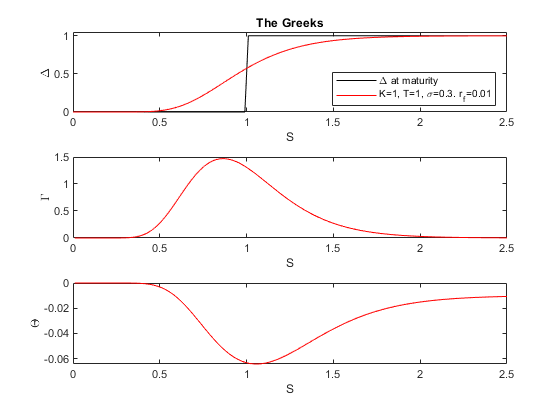

subplot(3,1,3); plot(S,theta,'r')
xlabel('S'); ylabel('\Theta')
xlim([0,2.5]); 

## Appendix

The function black_scholes_call() receives the present stock price $S$, the strike price $K$, the time to maturity dt, the risk-free rate $r_f$ and the annual volatility $\sigma$ as input and returns the options price $c$ from Equation 5.17 and $\Delta$ from Equation 5.22. $\Gamma$ is given in Equation 13.44 and $\theta$ can be evaluated by differentiation $c$ with respect to $T$.

function [c,delta,gamma,theta]=black_scholes_call(S0,K,dt,rf,sig)
N=@(z)0.5*erfc(-z/sqrt(2));
d1=(log(S0./K)+(rf+0.5.*sig.^2).*dt)./(sig.*sqrt(dt));
d2=(log(S0./K)+(rf-0.5.*sig.^2).*dt)./(sig.*sqrt(dt));
c=S0.*N(d1)-K.*exp(-rf.*dt).*N(d2);
delta=N(d1);
gamma=exp(-0.5*d1.^2)./(S0.*sqrt(2*pi*sig.^2.*dt));
theta=-0.5*(sig.^2).*(S0.^2).*gamma-rf.*K.*exp(-rf.*dt).*N(d2);
end